# 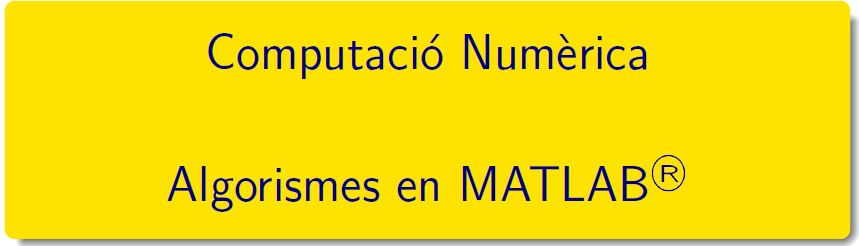

# Pràctica 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

El mètode iteratiu següent: convergeix a $\sqrt{2}$


$$x_k=\displaystyle\frac{1}{2}\left (x_{k-1}+\displaystyle\frac{2}{x_{k-1}}\right )\quad k\ge 1\ i\ x_0=3\,.$$


Calcular el valor $$x_{10}$$ fent ús de les instruccions

- bucle for

- bucle while

En tots els casos comparar el resultat obtingut amb el valor $$\sqrt{2} $$ . 

Calculeu els decimals correctes i les cifres significatives en cada iteració. Presenteu els resultats obtinguts en una taula.

**Solucions**

Calculem 5  iterats, no conservem els valors càlculats

xk = 3;
for k = 1:5
    xk = 0.5*(xk + 2/xk)
end

xk = 1.8333

xk = 1.4621

xk = 1.4150

xk = 1.4142

xk = 1.4142

Calculem 5 iterats, conservem els valors càlculats

xk = 3;
R = [xk];
for k = 1:5
    xk = 0.5*(xk + 2/xk);
    R = [R xk];
end
R

R =     3.0000    1.8333    1.4621    1.4150    1.4142    1.4142


Calculeu els 5 primers iterats, totes les iteracions en un vector, resultat en una estructura table.

xk = 3;
ea = abs(sqrt(2)-xk);
er = ea/sqrt(2);
R = [0, xk, ea, er];
for k = 1:5
    xk = 0.5*(xk + 2/xk);
    ea = abs(sqrt(2)-xk);
    er = ea/sqrt(2);
    R = [R; k, xk, ea, er];
end
T=array2table(R,'VariableNames',{'k','x_k','error_absolut', 'error_relatiu'}); disp(T)

    k     x_k      error_absolut    error_relatiu
    _    ______    _____________    _____________

    0         3         1.5858           1.1213  
    1    1.8333        0.41912          0.29636  
    2    1.4621       0.047908         0.033876  
    3     1.415     0.00078487       0.00055499  
    4    1.4142     2.1767e-07       1.5392e-07  
    5    1.4142     1.6653e-14       1.1776e-14  



### Qüestió oberta

Calculeu els ¿¿¿tots ???  els iterats, com s'atura el bucle

## 3. Aritmètica de PUNT FLOTANT

The memory format of an IEEE 754 double-precision floating-point value.

$fl(x)=(-1)^s\cdot \left(1+\frac{F}{2^{52}}\right)\cdot 2^{E-1023}$ per $s$ un bit, per $E$, l'exponent $11$ bits i per $F$, la part fraccionaria $52$bits

 Illustrated in byte-form, the exponent and fraction bits are distributed as:

[image: IEEE_754_Double_Floating_Point_Format.svg]   [crèdits imatge](https://commons.wikimedia.org/wiki/File:IEEE_754_Double_Floating_Point_Format.svg)

*0*0000000 0000**0000 00000000 00000000 00000000 00000000 00000000 00000000**

[Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

[A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)  o  [Floating Point Numbers](https://es.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html)

**Exercici 1.- Nombres binaris i nombres decimals**

- Convertim el nombre 9.5 a binari:

x = 17.25

x = 17.2500

- part entera, restes de dividir per 2

y = fix(x); r = rem(y,2); T = [y,r];
y = fix(y/2); r = rem(y,2), T = [T; y,r];

r = 0


 b = num2str(T(end:-1:1,2));
 fprintf('El nombre %f en binari és %s\n',fix(x),b)

El nombre 17.000000 en binari és 01


- part fraccionaria, multipliquem per 2 i ens quedem amb la part entera

z = x-fix(x);
y = 2*z; r = fix(y);  T = [z,r]; z = y-r;
y = 2*z; r = fix(y);  T = [T; z,r], z = y-r;

T =     0.2500         0
    0.5000    1.0000



 b2 = num2str(T(:,2));
 fprintf('El nombre %f en binari és %s\n',x-fix(x),b2)

El nombre 0.250000 en binari és 01


 fprintf('El nombre %f en binari és %s.%s\n',x,b,b2)

El nombre 17.250000 en binari és 01.01


**Exercici 2.- Aritmètica de punt flotant de 64 bits**

### LECTURA OBLIGATÒRIA: [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

Toby Driscoll (2021). IEEE 754 binary representation ([https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),](https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),) MATLAB Central File Exchange. Retrieved February 17, 2022.

[S,E,F] = ieee754(17)

S = '0'

E = '10000000011'

F = '0001000000000000000000000000000000000000000000000000'

**EXEMPLES**

**Avoiding Common Problems with Floating-Point Arithmetic**

Example 1 — Round-Off or What You Get Is Not What You Expect

- 4/3 no té fracció binària exacte

[S,E,F] = ieee754(4/3)

S = '0'

E = '01111111111'

F = '0101010101010101010101010101010101010101010101010101'

- 0.1 no té representació binària exacte

[S,E,F] = ieee754(0.1)

S = '0'

E = '01111111011'

F = '1001100110011001100110011001100110011001100110011010'

- L'ordre de les operacions pot fer variar el resultat del càlcul

- Hi ha "gaps" entre els números de punt flotant.  

- La representació de $\pi$ comporta que 

**Example 2 — Catastrophic Cancellation**

**Example 3 — Floating-Point Operations and Linear Algebra**

L'arrodoniment, la cancel·lació i altres caracterítiques de l'aritmètica de coma flotant es combinen per produir càlculs sorprenents en resoldre els problemes de l'àlgebra lineal. MATLAB adverteix que la següent matriu A està mal condicionada i, per tant, el sistema Ax = b pot ser sensible a petites pertorbacions:

**Example 4 — "Soroll numèric"**

## 4. Algorismes: Estabilitat numèrica i problemes ben condicionats

### Practiquem les funcions

#### Exercici 6. [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**  Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ 

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. Feu un joc de proves prenent $2^{-n},5^{-n},7^{-n},10^{-n}, \dots$

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

f = @(x)sqrt(x.^2 + 1)-1

f = function_handle with value:
    @(x)sqrt(x.^2+1)-1


g = @(x)(x.^2)./(sqrt(x.^2+1)+1)

g = function_handle with value:
    @(x)(x.^2)./(sqrt(x.^2+1)+1)


k = 1:20

k =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x = 8.^-k

x =     0.1250    0.0156    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


R = [k;f(x);g(x)]'

R =     1.0000    0.0078    0.0078
    2.0000    0.0001    0.0001
    3.0000    0.0000    0.0000
    4.0000    0.0000    0.0000
    5.0000    0.0000    0.0000
    6.0000    0.0000    0.0000
    7.0000    0.0000    0.0000
    8.0000    0.0000    0.0000
    9.0000         0    0.0000
   10.0000         0    0.0000


T = array2table(R, 'VariableNames', {'k', 'f', 'g'})

T = 20×3 table
    k         f             g     
    __    __________    __________

     1     0.0077822     0.0077822
     2    0.00012206    0.00012206
     3    1.9073e-06    1.9073e-06
     4    2.9802e-08    2.9802e-08
     5    4.6566e-10    4.6566e-10
     6     7.276e-12     7.276e-12
     7    1.1369e-13    1.1369e-13
     8    1.7764e-15    1.7764e-15
     9             0    2.7756e-17
    10             0    4.3368e-19
    11             0    6.7763e-21
    12             0    1.0588e-22
    13             0    1.6544e-24
    14             0    2.5849e-26
    15             0     4.039e-28
    16             0    6.3109e-30


disp(T)

    k         f             g     
    __    __________    __________

     1     0.0077822     0.0077822
     2    0.00012206    0.00012206
     3    1.9073e-06    1.9073e-06
     4    2.9802e-08    2.9802e-08
     5    4.6566e-10    4.6566e-10
     6     7.276e-12     7.276e-12
     7    1.1369e-13    1.1369e-13
     8    1.7764e-15    1.7764e-15
     9             0    2.7756e-17
    10             0    4.3368e-19
    11             0    6.7763e-21
    12             0    1.0588e-22
    13             0    1.6544e-24
    14             0    2.5849e-26
    15             0     4.039e-28
    16             0    6.3109e-30
    17             0    9.8608e-32
    18             0    1.5407e-33
    19             0    2.4074e-35
    20             0    3.7616e-37



#### Exercici 8. [Funcions en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

`function f = nom_fun(``arglist``)`

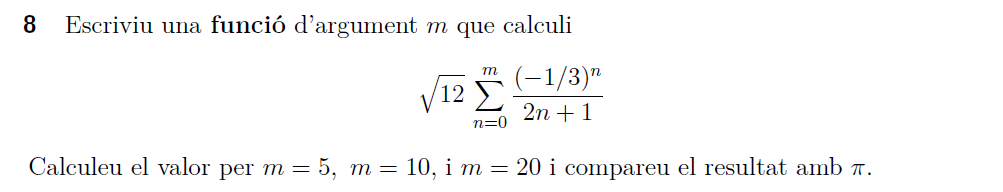

a = ex8(20)

a = 3.1416

**11** **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos mètodes iteratius diferents:

	            
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

- apartat a)

I(50) = 0;
for n = 50:-1:2
    I(n-1) = (1-I(n))/n;
end

- apartat b)

I2(1) = 1/exp(1);
for n = 2:50
    I2(n) = 1-n*I(n-1);
end

- valor aproximat per integració numèrica

for i = 1:50
    v(i) = integral( @(x)x.^i.*exp(x-1),0,1);
end

- Taula comparativa de resultats

k = 1:50;
R = [k; I; I2; v]';
T = array2table(R, 'VariableNames', {'i', 'I', 'J', 'Integracio Numerica'});
disp(T)

    i        I           J        Integracio Numerica
    __    ________    ________    ___________________

     1     0.36788     0.36788          0.36788      
     2     0.26424     0.26424          0.26424      
     3     0.20728     0.20728          0.20728      
     4     0.17089     0.17089          0.17089      
     5     0.14553     0.14553          0.14553      
     6      0.1268      0.1268           0.1268      
     7     0.11238     0.11238          0.11238      
     8     0.10093     0.10093          0.10093      
     9    0.091612    0.091612         0.091612      
    10    0.083877    0.083877         0.083877      
    11    0.077352    0.077352         0.077352      
    12    0.071773    0.071773         0.071773      
    13    0.066948    0.066948         0.066948      
    14    0.062732    0.062732         0.062732      

- Taula comparativa d'errors

R2 = [k; abs(I-v); abs(I-v)./v; abs(I2-v); abs(I2-v)./v]';
T2 = array2table(R2, 'VariableNames', {'i', 'Ea1', 'Er1', 'Ea2', 'Er2'});
disp(T2)

    i        Ea1           Er1           Ea2           Er2    
    __    __________    __________    __________    __________

     1             0             0             0             0
     2    5.5511e-17    2.1008e-16    5.5511e-17    2.1008e-16
     3    2.7756e-17    1.3391e-16    8.3267e-17    4.0172e-16
     4             0             0    5.5511e-17    3.2483e-16
     5    2.7756e-17    1.9072e-16    1.6653e-16    1.1443e-15
     6             0             0    5.5511e-17    4.3778e-16
     7    1.3878e-17    1.2349e-16    4.1633e-17    3.7046e-16
     8             0             0    2.7756e-17    2.7499e-16
     9    1.3878e-17    1.5148e-16    1.3878e-17    1.5148e-16
    10             0             0    1.3878e-17    1.6545e-16
    11             0             0    6.9389e-17    8.9705e-16
    12    

## Pràctica

## 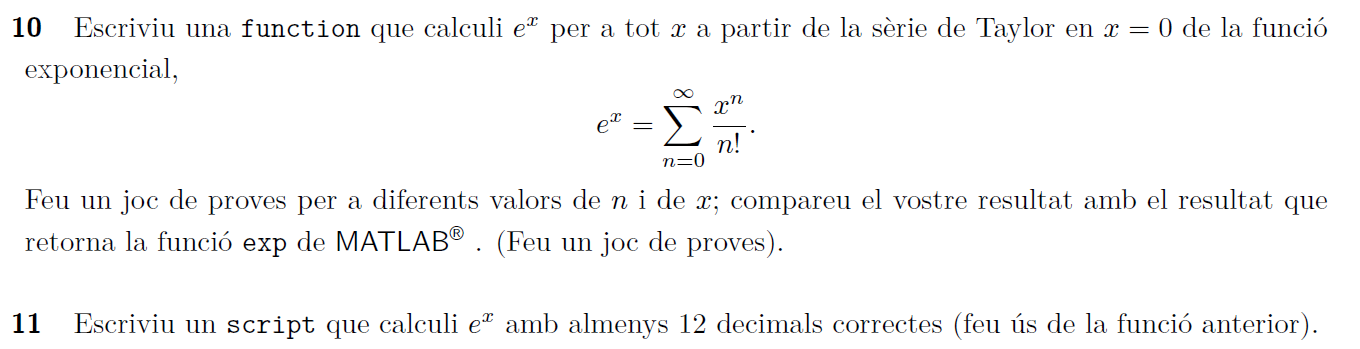     

`Document preparat per M. Àngela Grau Gotés, 15 de febrer de 2023`

function f = ex8(m)
    sum = 0;
    for n = 0:m
        sum = sum + (((-1/3)^n)/(2*n+1));
    end
    f = sqrt(12)*sum;
end
